# Experiment 1: SIFT + NB (Whole Image)

## Clean environment

close all;
clear variables;
clc;
rng(42);

## Set folder path

folder = "C:\Users\u3253992\workspace\computer-vision\assignment_1\u3253992_assignment_1\data\CUB_200_2011_Subset20classes\";

## Load dataset

[trainingImageNames, validationImageNames, testImageNames, classNames, imageClassLabels] = loadDataset(folder);

No bounding Box


## Create datastores

disp('Training set class distribution:');

Training set class distribution:


trainingImageDS = createImageDatastore(trainingImageNames, folder);

    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  
     017      34  
     018      26  
     019      35  
     020      35  




disp('Validation set class distribution:');

Validation set class distribution:


validationImageDS = createImageDatastore(validationImageNames, folder);

    Label    Count
    _____    _____

     001       6  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  
     017      12  
     018      10  
     019      12  
     020      12  




disp('Test set class distribution:');

Test set class distribution:


testImageDS = createImageDatastore(testImageNames, folder);

    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  
     017      11  
     018       9  
     019      12  
     020      12  



## Resize image datastores and combine them with the labels

targetSize = [128 128]

targetSize =    128   128


trainCDS = resizeCombineDatastore(trainingImageDS, targetSize);
valCDS = resizeCombineDatastore(validationImageDS, targetSize);
testCDS = resizeCombineDatastore(testImageDS, targetSize);

## Show images

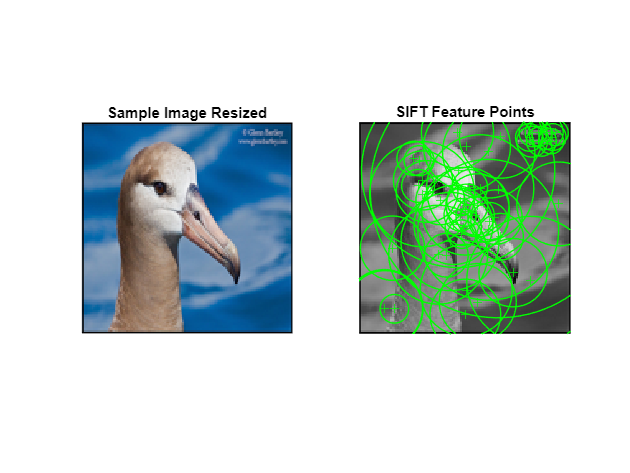

ans = 0

showImageFeatures(trainCDS)

## Extract SIFT features

numFeatures = 50;
maxFeatures = 100;

[trainingFeatures, trainingLabels] = extractSIFTFeaturesFromDatastore(trainingImageDS, numFeatures, maxFeatures);
[testFeatures, testLabels] = extractSIFTFeaturesFromDatastore(testImageDS, numFeatures, maxFeatures);

## Enables GPU

[device, useGPU] = enableGPU();

✅ GPU found and ready:
  CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 3070'
                Index: 1 (of 1)
    ComputeCapability: '8.6'
          DriverModel: 'WDDM'
          TotalMemory: 8589410304 (8.59 GB)
      AvailableMemory: 5775305932 (5.78 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

## Train classifier

NBClassifier = fitcnb(trainingFeatures, trainingLabels, "DistributionNames","kernel", "Standardize", true);

## Evaluate

[accuracy, predictions] = evaluateClassifier(NBClassifier, testFeatures, testLabels);

## Plot confusion matrix

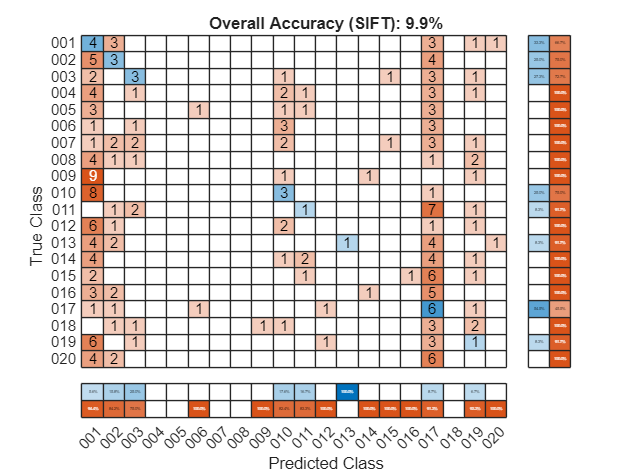

Classwise Recognition Rates:
   33.3000
   25.0000
   27.3000
         0
         0
         0
         0
         0
         0
   25.0000
    8.3000
         0
    8.3000
         0
         0
         0
   54.5000
         0
    8.3000
         0



plotConfusionMatrix(testLabels, predictions, "Overall Accuracy (SIFT): " + string(round(accuracy*100, 1)) + "%");